# HW 2

clear;close;clc;
syms x
f = 3*x^2-6*x-2

$$f = 3\,x^{2}-6\,x-2$$

expand(f)

$$ans = 3\,x^{2}-6\,x-2$$

collect(f)

$$ans = 3\,x^{2}-6\,x-2$$

simplify(f)

$$ans = 3\,x^{2}-6\,x-2$$

factor(f,'FactorMode',"full")

$$ans = \left(\begin{array}{ccc} 3 & x+\frac{\sqrt{15}}{3}-1 & x-\frac{\sqrt{15}}{3}-1 \end{array}\right)$$

vpa(factor(f,'FactorMode',"full"))

$$ans = \left(\begin{array}{ccc} 3.0 & x+0.29099444873580562839308846659413 & x-2.2909944487358056283930884665941 \end{array}\right)$$


fplot(@(x) x*(1-x)*(2-x))

hold on 
fplot(@(x) x==0)
hold on 

f = x*(1-x)*(2-x)

$$f = x\,\left(x-1\right)\,\left(x-2\right)$$

fp=diff(f,x)

$$fp = \left(x-1\right)\,\left(x-2\right)+x\,\left(x-1\right)+x\,\left(x-2\right)$$

collect(fp)

$$ans = 3\,x^{2}-6\,x+2$$

subs(fp,x,2)

$$ans = 2$$


clear;close;clc;
syms x
f = x^2*(6-x)

$$f = -x^{2}\,\left(x-6\right)$$

fplot(@(x) f);

hold on; grid on;

clear;close;clc;
syms x(t) a b
f = -a*x*log(b*x)

$$f(t) = -a\,\log\left(b\,x\left(t\right)\right)\,x\left(t\right)$$

s = diff(f,t)

$$s(t) = -a\,\frac{\partial }{\partial t}x\left(t\right)-a\,\log\left(b\,x\left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)$$

fplot(@(x) s);

hold on; grid on;
solve(s==0)

 
ans =
 
Empty sym: 0-by-1
 



clear;close;clc;
syms x a b
xd = -a*x*log(b*x)

$$xd = -a\,x\,\log\left(b\,x\right)$$

%f = -a*(xd-log(b*x)*xd)
f = -a*(xd*log(b*x) - xd/b)

$$f = a\,\left(a\,x\,{\log\left(b\,x\right)}^{2}-\frac{a\,x\,\log\left(b\,x\right)}{b}\right)$$

solve(f==0,x)

$$ans = \left(\begin{array}{c} \frac{{\mathrm{e}}^{1/b}}{b}\\ \frac{1}{b} \end{array}\right)$$

solve(xd==0,x)

$$ans = \frac{1}{b}$$

fplot(@(x) subs(subs(f,a,5),b,7));

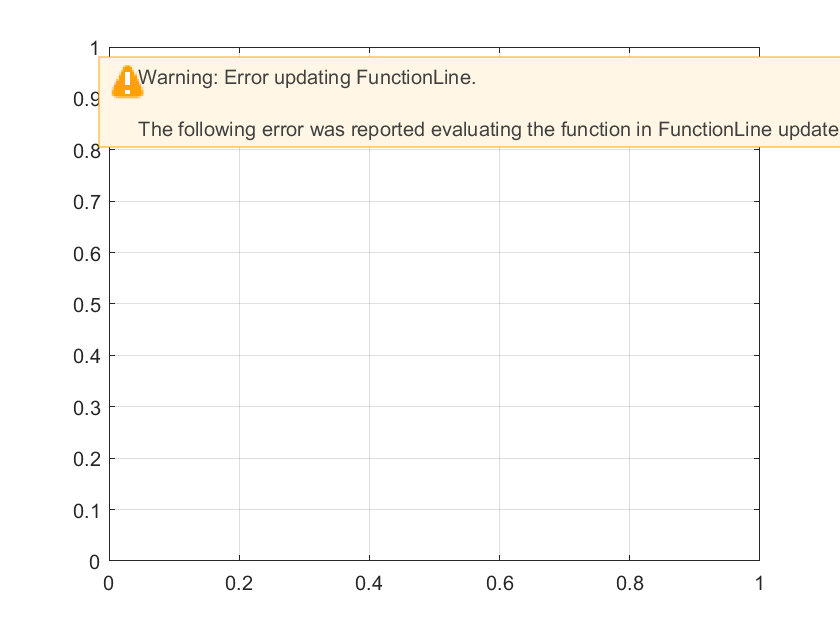

hold on; grid on;

subs(f,x,(1/b))

$$ans = 0$$


syms x k m g
solve(0 == -2*k*m*x^2+g)

$$ans = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{g}}{2\,\sqrt{k}\,\sqrt{m}}\\ \frac{\sqrt{2}\,\sqrt{g}}{2\,\sqrt{k}\,\sqrt{m}} \end{array}\right)$$